clc;
close all;
clear variables;

## Creating a datastore for my images

folder_name = fullfile(pwd, 'data');
imds = imageDatastore(folder_name, 'LabelSource',"foldernames");
raw_images = readall(imds);


### Label data 

Get label from filename

imds.Labels = char(imds.Labels); % turn labes to char
N = length(imds.Files);
for i = 1:N
    filename = imds.Files{i}(length(folder_name) + 1:end);
    left_parenth_index = find(filename == ' ');
    label = filename(2:left_parenth_index - 1);
    if strcmp(label, 'prazna')
        label = 'E';
    elseif strcmp(label,'pune')
        label = 'F';
    end
    imds.Labels{i} = label;
end

Only full balls

full_ball_imds = subset(imds, [imds.Labels{:}] == 'F');

## Preprocessing images

target_size = [600, 600];
final_size = [200, 200];

preprocessed_imds = transform(full_ball_imds, @(x) imresize(x, target_size));

Downsample images for easier computation

preprocessed_imds = transform(preprocessed_imds, @(x) imresize(x, final_size));

preprocessed_imds = transform(preprocessed_imds, @(x) rgb2gray(x));

preprocessed_imds = transform(preprocessed_imds, @(x) edge(x, 'Canny'));

N = length(full_ball_imds.Files);
preprocessed_images = my_readall(preprocessed_imds, N);

### Display preprocessed images

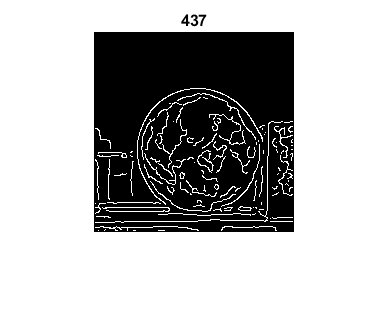

for i=1:1
    figure();
    rand_int = randi(N);
    imshow(preprocessed_images{rand_int})
    title(rand_int)
end

## Feature extraction

I = preprocessed_images{rand_int};
figure('Position', [10 10 900 600]);
imshow(I);
hold on

% hog surf and kaze are good for classification apparently
% https://www.mathworks.com/help/vision/ug/local-feature-detection-and-extraction.html

HOG, surf and kaze are good for classification apparently.

[https://www.mathworks.com/help/vision/ug/local-feature-detection-and-extraction.html](https://www.mathworks.com/help/vision/ug/local-feature-detection-and-extraction.html)

method_name = "hog";
num_points = 10;
cell_size = [10, 10];


Histogram of oriented gradients

if method_name == "hog"
    [featureVector, visualization] = extractHOGFeatures(I,'CellSize',cell_size);
    plot(visualization, 'Color','red')
    

SURF

elseif method_name == "surf"
    points = detectSURFFeatures(I).selectStrongest(num_points);
    [features, valid_points] = extractFeatures(I, points);
    plot(valid_points);
    

KAZE

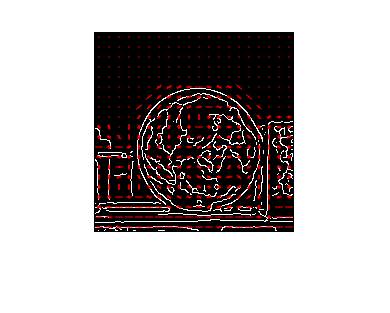

elseif method_name == "kaze"
    points = detectKAZEFeatures(I).selectStrongest(num_points);
    [features, valid_points] = extractFeatures(I, points);
    plot(valid_points);
end
hold off

### Extract features

if method_name == "hog"
    features_ds = transform(preprocessed_imds, @(x) extractHOGFeatures(x, 'CellSize',cell_size));
end


data = double(cell2mat(my_readall(features_ds, N)));

### Dimensionality reduction

### Principal component analysis

[coeff,~,~,~,explained,~] = pca(data);

% of info contained in each coordinate

explained

explained =     8.7540
    4.0736
    3.6625
    3.0281
    2.5029
    1.6696
    1.4865
    1.3511
    1.2965
    1.1214


feature_vector_size = 100; % less is more?

% of info contained in the chosen *feature_vector_size* coordinates

sum(explained(1:feature_vector_size))

ans = 61.5292

A_dim_reduction = coeff(:, 1:feature_vector_size);

Data times chosen eigenvectors matrix

features_ds = transform(features_ds, @(x) x * A_dim_reduction);
data_low_dim = double(cell2mat(my_readall(features_ds, N)));

## Clustering

idx = kmeans(data_low_dim, 2)

idx =      1
     1
     2
     2
     1
     1
     1
     2
     1
     1


idx == 1

ans = 1052×1 logical array
   1
   1
   0
   0
   1
   1
   1
   0
   1
   1


cluster_1 = subset(preprocessed_imds, idx == 1);
cluster_1_imgs = my_readall(cluster_1, sum(idx == 1));

cluster_2 = subset(preprocessed_imds, idx == 2);
cluster_2_imgs = my_readall(cluster_2, sum(idx == 2));

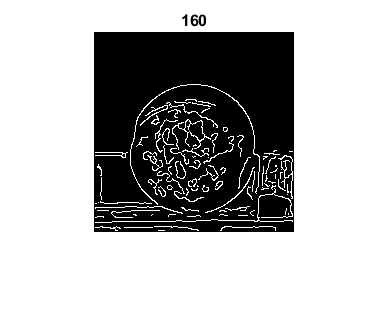

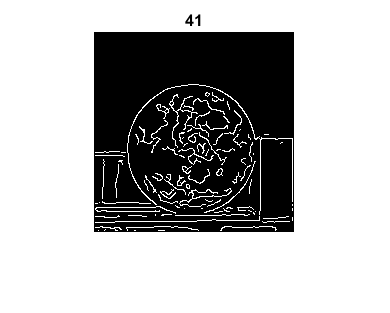

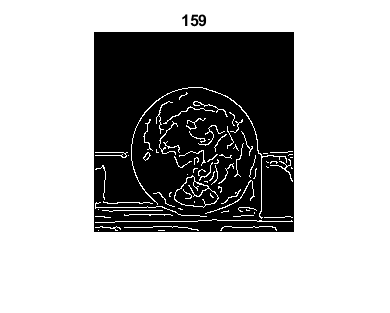

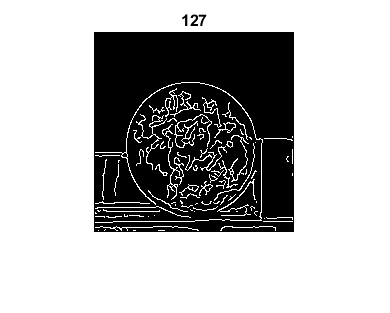

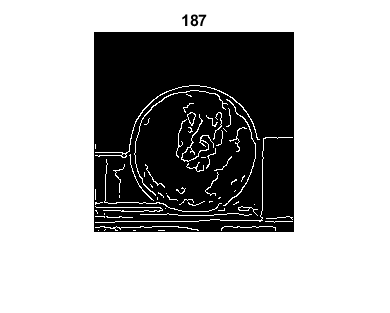


for i=1:5
    figure();
    rand_int = randi(sum(idx == 1));
    imshow(cluster_1_imgs{rand_int})
    title(rand_int)
end

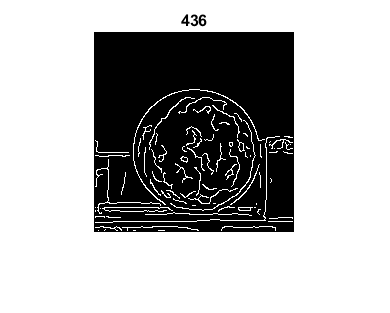

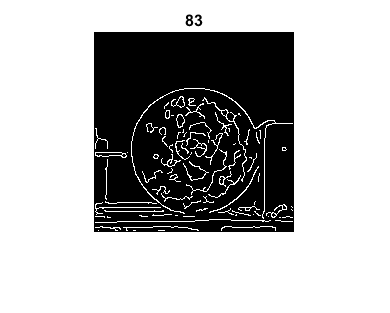

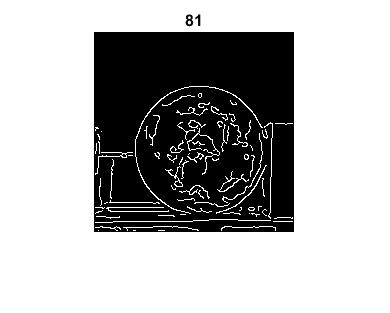

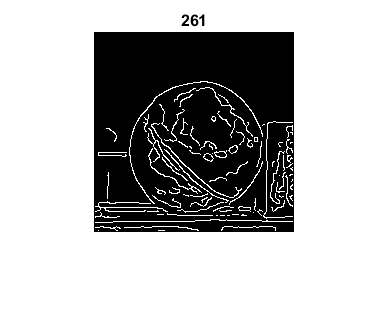

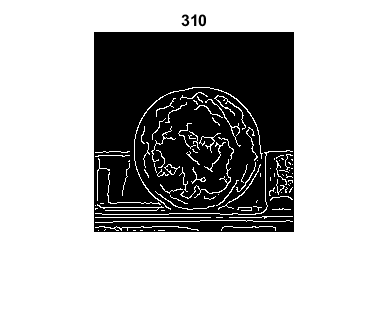


for i=1:5
    figure();
    rand_int = randi(sum(idx == 2));
    imshow(cluster_2_imgs{rand_int})
    title(rand_int)
end